# Immo

Inspiration: [https://github.com/slevin48/immo](https://github.com/slevin48/immo)

Data source: [https://www.data.gouv.fr/fr/datasets/5cc1b94a634f4165e96436c1/](https://www.data.gouv.fr/fr/datasets/5cc1b94a634f4165e96436c1/) 

setup;

Defaulting to user installation because normal site-packages is not writeable


% pipshow('pandas')
% websave('immo.py','https://raw.githubusercontent.com/slevin48/immo/master/immo.py')

Example in Paris (14th arrondissement)

commune = "75114";
price_min = 7500;
price_max = 12000;
date_start = datetime("2023-03-14", "InputFormat", "uuuu-MM-dd");

% Python code input
pycode3 = [...
"import pandas as pd",...
"",...
"def load_data(code_commune):",...
"    # json_data = immo.dvf_commune(postcode)",...
"    url = ""https://files.data.gouv.fr/geo-dvf/latest/csv/2023/communes/""+str(code_commune)[:2]+""/""+str(code_commune)+"".csv""",...
"    df = pd.read_csv(url)",...
"    df.date_mutation = pd.to_datetime(df.date_mutation)",...
"    df = df.dropna(subset=['valeur_fonciere','surface_reelle_bati','longitude','latitude'])",...
"    df['prixm2'] = df.valeur_fonciere/df.surface_reelle_bati",...
"    df = df[df.prixm2>1000] ",...
"    df = df[df.prixm2<15000] ",...
"    df.prixm2 = df.prixm2.astype(int)",...
"    df['marker_color'] = pd.cut(df['prixm2'], bins=4,labels=['blue','green', 'yellow', 'red'])",...
"    df = df.sort_values(by='date_mutation',ascending=False)",...
"    return df",...
"",...
"# commune = 75114",...
"df = load_data(commune)"...
];

[df] = pyrun(pycode3, ...
     [ "df" ]);

% Clean up
clear pycode3;
T = table(df);
T = T(T.prixm2 > price_min & T.prixm2 < price_max & T.date_mutation > date_start,{'id_mutation','date_mutation','valeur_fonciere','prixm2','adresse_numero','adresse_nom_voie','latitude','longitude','marker_color'})

T = 369x9 table
     id_mutation     date_mutation    valeur_fonciere    prixm2    adresse_numero       adresse_nom_voie        latitude    longitude    marker_color
    _____________    _____________    _______________    ______    ______________    _______________________    ________    _________    ____________

    "2023-563211"     30-Jun-2023        1.275e+06       11486           21          "VLA D ALESIA"              48.828      2.3242         red      
    "2023-564028"     30-Jun-2023            5e+05        9803           49          "RUE SARRETTE"              48.825      2.3275         yellow   
    "2023-563251"     30-Jun-2023         1.08e+05        9818           17  

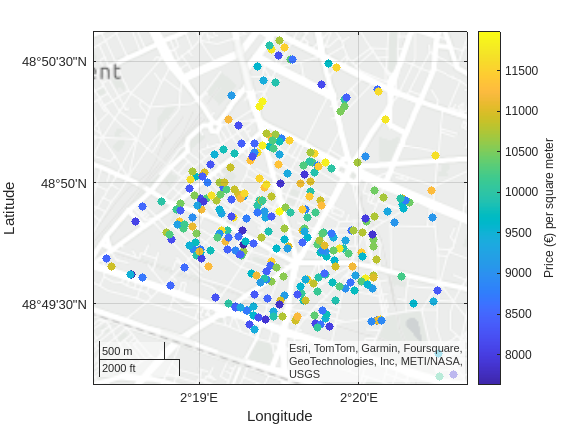

s = geoscatter(T,"latitude","longitude","filled");
s.ColorVariable = "prixm2";
c = colorbar;
c.Label.String = "Price (€) per square meter";

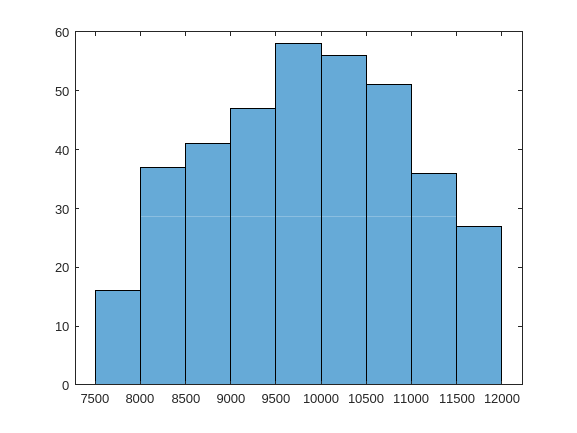

histogram(T.prixm2)